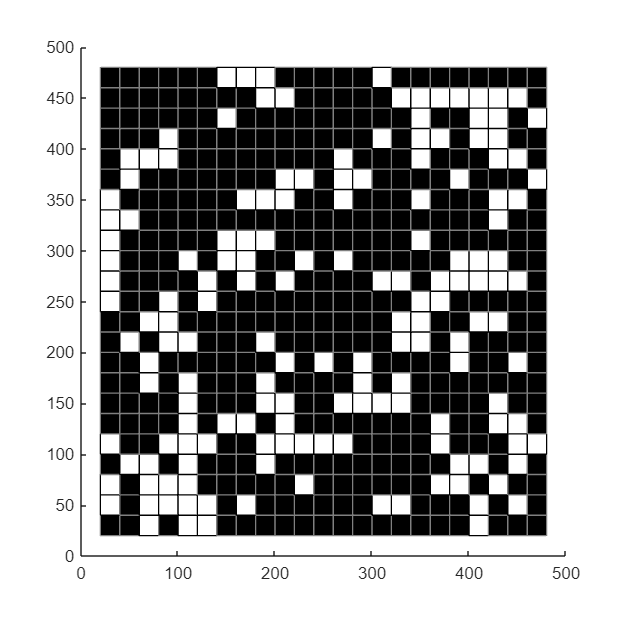

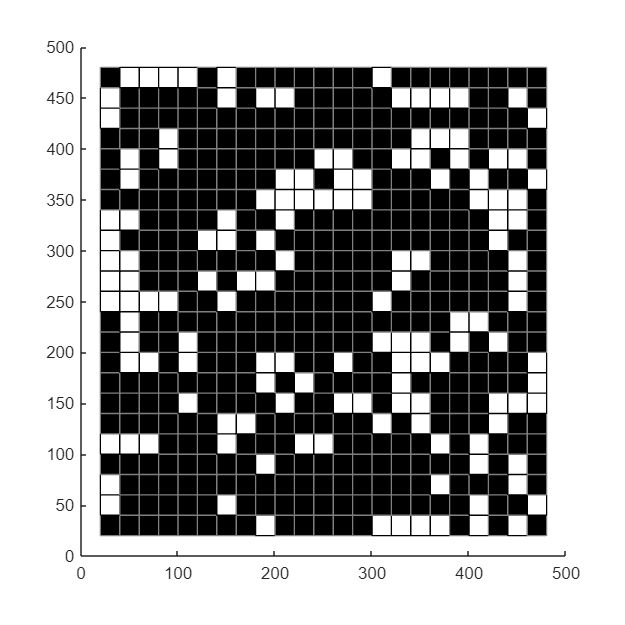

% programacion del juego de la vida ed conway

% variables
filas = 500;
columnas = 500;

% para que se muestre en una ventana
figure('Name', 'Juego de la Vida', 'NumberTitle', 'off', 'Position', [150, 130, filas, columnas]);
hold on;

celdasX = 25;   % cuadros en x
celdasY = 25;   % cuadros en y

% Dimensiones de los cuadros (en pixeles)
dimF = filas / celdasX;   
dimC = columnas / celdasY;

% Se inicia aleatoriamente la poblacion
% viva - 1      muerta - 0
mundo = randi([0,1],celdasX,celdasY);

while true
    nuevo_mundo = mundo;

    clf;    % vacia la figura

    for y = 2:celdasY-1
        for x = 2:celdasX-1
            
            % suma la cantidad de vecinos
            vecinas = mundo(x-1,y-1) + mundo(x,y-1) + mundo(x+1,y-1) + mundo(x-1,y) + mundo(x+1,y) + mundo(x-1,y+1) + mundo(x,y+1) + mundo(x+1,y+1);

            %       Si una celda muerta tiene exactamente 3 celdas vecinas vivas su estado pasa a estar viva
            if mundo(x, y) == 0 && vecinas == 3
                nuevo_mundo(x, y) = 1;

            %       Si una celda viva tiene menos de 2 o más de 3 celdas vecinas vivas muere
            elseif mundo(x, y) == 1 && (vecinas < 2 || vecinas > 3)
                nuevo_mundo(x, y) = 0;
            end

            % Se colorean en la figura
            if nuevo_mundo(x, y) == 0
                rectangle('Position', [(x-1)*dimF, (y-1)*dimC, dimF, dimC], 'EdgeColor', [0.5, 0.5, 0.5], 'FaceColor', [0, 0, 0]);
            else
                rectangle('Position', [(x-1)*dimF, (y-1)*dimC, dimF, dimC], 'FaceColor', [1, 1, 1]);
            end
        end
    end

    mundo = nuevo_mundo;    % actualiza el nuevo mundo

    pause(0.01);
end